clc;

clear;

imds =imageDatastore('database','IncludeSubfolders',true,'LabelSource','foldernames');

for i = 1:numel(imds.Files) % Read images using a for loop

img = readimage(imds,i);

trainingfeatures(i,:) = extractHOGFeatures(img,'CellSize',[8 8]);

end

traininglabels=imds.Labels;

ImageData = array2table(trainingfeatures);

ImageData.DigitLabels = traininglabels;

[filename, pathname] = uigetfile('*.*', 'Pick a MATLAB code file');

filename = strcat(pathname,filename);

img = imread(filename);
testFaetures = extractHOGFeatures(img, 'CellSize', [8 8]);

[trainedClassifier, validationAccuracy] = trainClassifier(ImageData);

[bestGuess score] = predict(trainedClassifier.ClassificationSVM, testFaetures);

clc;

disp('Class');

Class



disp(bestGuess);

     7 



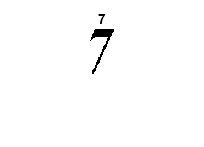


imshow(img);title(bestGuess)


disp('exit');

exit
